clc, clearvars;
function [MOVINGREG] = registerMarsImages(MOVING,FIXED)

% Feature-based techniques require license to Computer Vision Toolbox
checkLicense()

% Default spatial referencing objects
fixedRefObj = imref2d(size(FIXED));
movingRefObj = imref2d(size(MOVING));

% Detect SURF features
fixedPoints = detectSURFFeatures(FIXED,'MetricThreshold',750.000000,'NumOctaves',3,'NumScaleLevels',5);
movingPoints = detectSURFFeatures(MOVING,'MetricThreshold',750.000000,'NumOctaves',3,'NumScaleLevels',5);

% Extract features
[fixedFeatures,fixedValidPoints] = extractFeatures(FIXED,fixedPoints,'Upright',false);
[movingFeatures,movingValidPoints] = extractFeatures(MOVING,movingPoints,'Upright',false);

% Match features
indexPairs = matchFeatures(fixedFeatures,movingFeatures,'MatchThreshold',50.000000,'MaxRatio',0.500000);
fixedMatchedPoints = fixedValidPoints(indexPairs(:,1));
movingMatchedPoints = movingValidPoints(indexPairs(:,2));
MOVINGREG.FixedMatchedFeatures = fixedMatchedPoints;
MOVINGREG.MovingMatchedFeatures = movingMatchedPoints;

% Apply transformation - Results may not be identical between runs because of the randomized nature of the algorithm
tform = estimateGeometricTransform2D(movingMatchedPoints,fixedMatchedPoints,'projective');
MOVINGREG.Transformation = tform;
MOVINGREG.RegisteredImage = imwarp(MOVING, movingRefObj, tform, 'OutputView', fixedRefObj, 'SmoothEdges', true);

% Store spatial referencing object
MOVINGREG.SpatialRefObj = fixedRefObj;

end

function checkLicense()

% Check for license to Computer Vision Toolbox
CVTStatus = license('test','Video_and_Image_Blockset');
if ~CVTStatus
    error(message('images:imageRegistration:CVTRequired'));
end

end

% Load the images
fixedImg = im2gray(imread("sol_03333_opgs_edr_ncam_NLB_693387385EDR_F0921230NCAM00259M_.JPG"));
leftImg = im2gray(imread("sol_03333_opgs_edr_ncam_NLB_693387301EDR_F0921230NCAM00259M_.JPG"));

% Register the two images
reg = registerMarsImages(leftImg, fixedImg)

reg = struct with fields:
     FixedMatchedFeatures: [125×1 SURFPoints]
    MovingMatchedFeatures: [125×1 SURFPoints]
           Transformation: [1×1 projective2d]
          RegisteredImage: [1024×1024 uint8]
            SpatialRefObj: [1×1 imref2d]


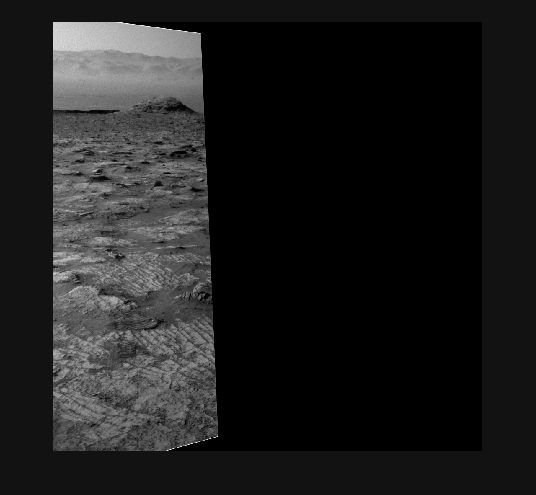

movingT = reg.Transformation;
fixedT = rigidtform2d();

figure; imshow(reg.RegisteredImage)

[nrows, ncols, ~] = size(leftImg);
[xlimMoving, ylimMoving] = outputLimits(movingT,[1 ncols],[1 nrows])

xlimMoving = 1×2 single row vector
1.0e+03 *

   -1.0476    0.3945


ylimMoving = 1×2 single row vector
1.0e+03 *

   -0.1623    1.3854


[nrows1, ncols1, ~] = size(fixedImg);
[xlimFixed, ylimFixed] = outputLimits(fixedT,[1 ncols1],[1 nrows1])

xlimFixed =            1        1024


ylimFixed =            1        1024


% Find the smallest and largest extents in the world coordinate system
xMin = min([xlimMoving, xlimFixed])

xMin = single
-1.0476e+03

xMax = max([xlimMoving, xlimFixed])

xMax = single
1024

yMin = min([ylimMoving, ylimFixed])

yMin = single
-162.3299

yMax = max([ylimMoving, ylimFixed])

yMax = single
1.3854e+03

% Width and height of panorama.
w  = round(xMax - xMin);
h = round(yMax - yMin);

% Initialize the empty panorama. This is a color image.
panorama = zeros([h, w, 3],"uint8");

blender = vision.AlphaBlender("Operation","Binary Mask","MaskSource","Input port")

blender =   vision.AlphaBlender with properties:

         Operation: 'Binary mask'
        MaskSource: 'Input port'
    LocationSource: 'Property'
          Location: [1 1]


panoramaView = imref2d([h w],[xMin xMax],[yMin yMax])

panoramaView =   imref2d with properties:

           XWorldLimits: [-1.0476e+03 1024]
           YWorldLimits: [-162.3299 1.3854e+03]
              ImageSize: [1548 2072]
    PixelExtentInWorldX: 0.9998
    PixelExtentInWorldY: 0.9999
    ImageExtentInWorldX: 2.0716e+03
    ImageExtentInWorldY: 1.5478e+03
       XIntrinsicLimits: [0.5000 2.0725e+03]
       YIntrinsicLimits: [0.5000 1.5485e+03]


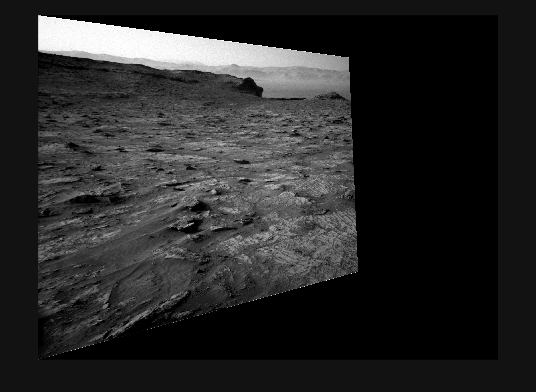

movingWarped = imwarp(leftImg,movingT,"OutputView",panoramaView);
fixedWarped = imwarp(fixedImg,fixedT,"OutputView",panoramaView);
imshow(movingWarped)

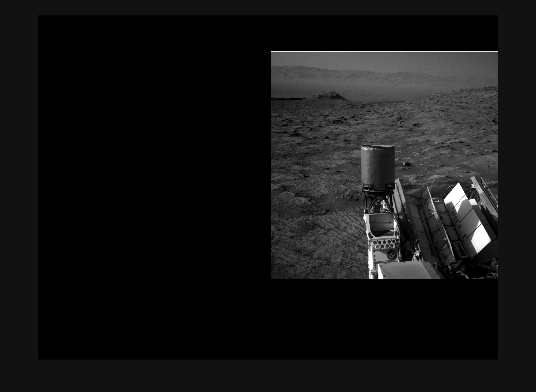

imshow(fixedWarped)

% Initialize masks with correct dimensions
movingMask = ones(nrows, ncols, "logical");  % Mask for moving image (leftImg)
fixedMask = ones(nrows1, ncols1, "logical"); % Mask for fixed image (fixedImg)

% Warp masks into panorama coordinates
fixedMask = imwarp(fixedMask, fixedT, "OutputView", panoramaView); % Warp fixed image's mask
movingMask = imwarp(movingMask, movingT, "OutputView", panoramaView); % Warp moving image's mask

% Blend images in correct order
panorama = blender(panorama, fixedWarped, fixedMask); % Fixed image first

Error using AlphaBlender
The Image 1 and Image 2 inputs must have the same number of dimensions.

panorama = blender(panorama, movingWarped, movingMask); % Moving image second
imshow(panorama)